# Efecto integral

% Para el sistema 



$$\begin{array}{l}
\dot{x} =x+u\\
y=x
\end{array}$$


a=1;b=1;c=1;d=0;
% polo deseados pd={ -2 -2}  s=-2 para ki   y s=-2 para k
pd=[-2 -2];


Sistema aumentado  variables  $x_a =\left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack$


$$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -c\\
0 & a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


Aa=[0 -c;
    0  a];
Ba=[0; b];
Br=[1 ;0];
Ka=acker(Aa,Ba,pd);
Ki=-Ka(1) ;K=Ka(2);
% Polos del Sistema controlado
eig(Aa-Ba*Ka)

ans =    -2.0000
   -2.0000



% Planta controlada
% Ley de control  u= Kixi-Kx


$$u=-\left\lbrack \begin{array}{cc}
{-K}_i  & K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -c\\
0 & a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{-K}_i  & K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$



$$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -c\\
0 & a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 0\\
-K_i  & K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$



$$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -c\\
K_i  & \left(a-K\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


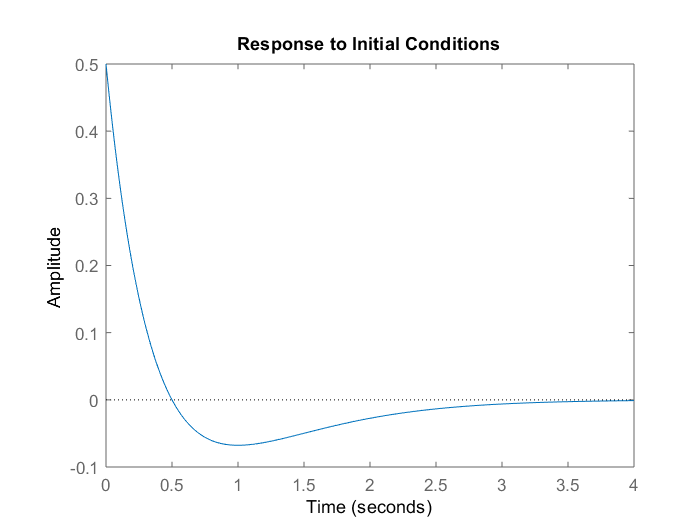


Ca=[0 1]; Da=0;
sysc=ss(Aa-Ba*Ka,Br,Ca,Da);

% respuesta a la condición inicial  x(0)=[0;0.5]
x0=[0;0.5];
initial(sysc,x0);

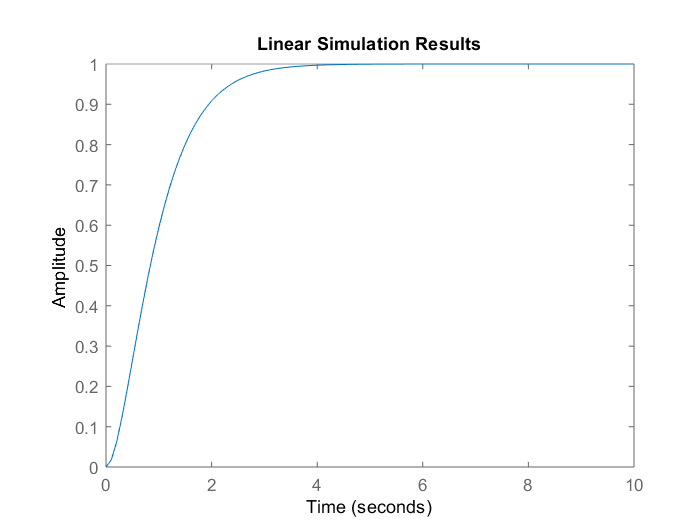

t = 0:0.1:10;                % vector of time samples
r = ones(1,length(t));       % 
lsim(sysc,r,t)

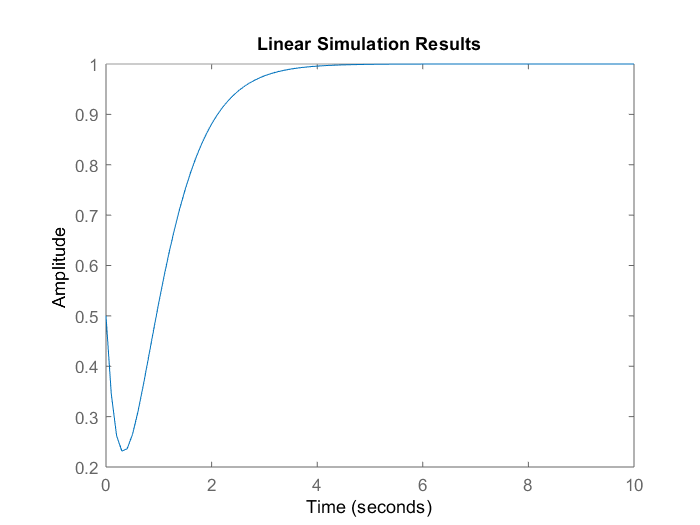

lsim(sysc,r,t,x0)

% respuesta a una perturbación despues de haber alcanzado el 
% equilibrio
d=1.*(t<=5)+2.*(t>5);

$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -c\\
K_i  & \left(a-K\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$+$\left\lbrack \begin{array}{c}
0\\
b
\end{array}\right\rbrack d$

sysc_d=ss(Aa-Ba*Ka,[Br Ba],Ca,[Da 0])


sysc_d =
 
  A = 
       x1  x2
   x1   0  -1
   x2   4  -4
 
  B = 
       u1  u2
   x1   1   0
   x2   0   1
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



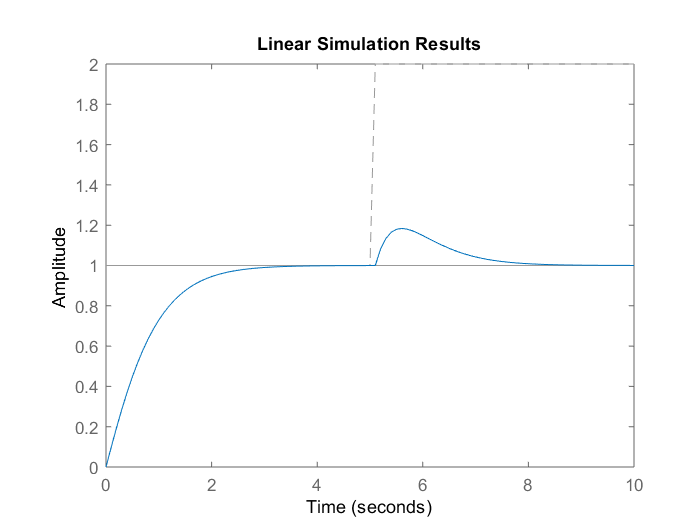


%
lsim(sysc_d,[r' d'],t)